# **Anti-reflection coating**

     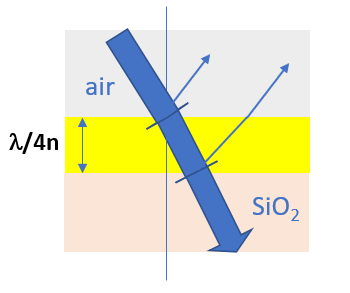

## Data 

% Refractive indices
n_air = 1; 
n_subtrat = 1.51; 
n_layer = sqrt(n_air*n_subtrat);
index = [n_air n_layer n_subtrat]; %  [supstrat layers substrat]
%
% Geometry
wl = .65; % Wavelength reference (µm)
geom = wl/(4*n_layer); % Layer Thickness (µm)
%

## Spectrum Computation versus wavelength

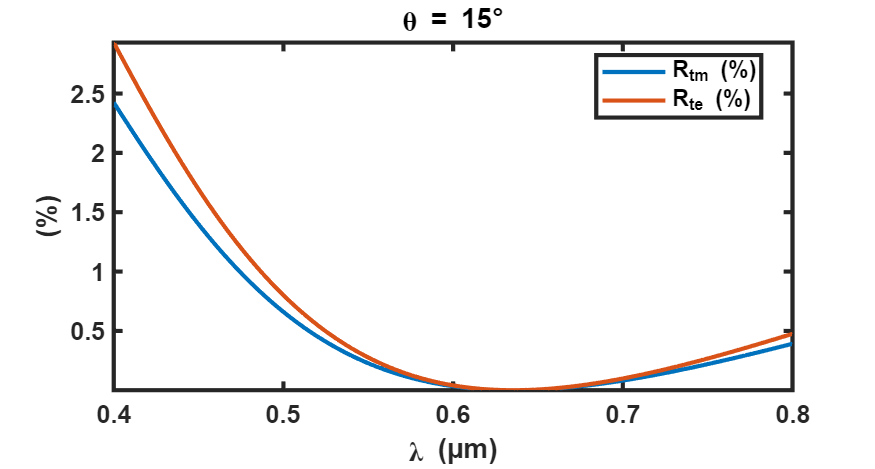

% Incident Plane Wave
lambda = linspace(0.4,0.8,101); % Wavelength(µm)
theta = 15*pi/180;              % Incident angle (rd)
inc = +1; % inc = -1: from down, +1: from top
%
% Spectrum Computation versus wavelength (lambda) for a defined incident angle 
[R_tm,T_tm,R_te,T_te] = Spectrum(index,geom,lambda,theta,inc);
%
% Plot Reflection versus wave-length in TM and TE polarisation 
figure('Position',[300  300  560  300]), 
PlotCoefRTA(lambda,theta,R_tm,R_te), legend('R_{tm} (%)','R_{te} (%)'), axis tight

## Spectrum Computation versus incident angle

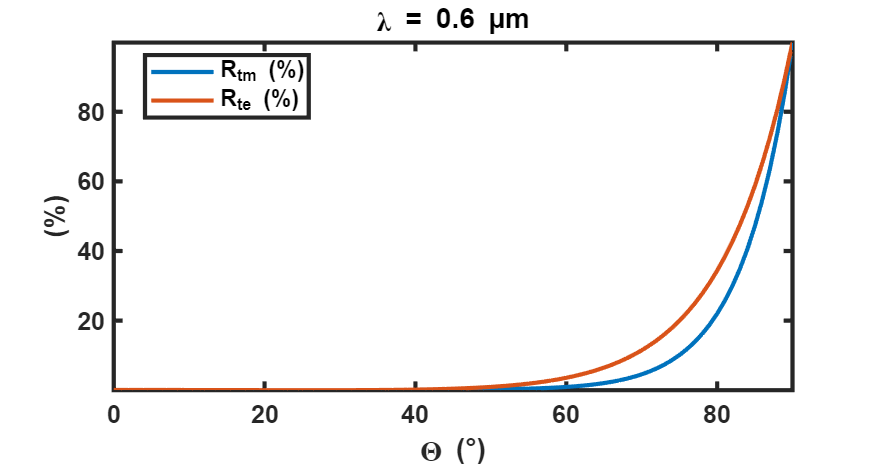

% Incident Plane Wave
lambda = 0.6; 
theta = linspace(0,89.99,91)*pi/180; 
inc = +1; % inc = -1: from down, +1: from up
%
% Spectrum Computation versus incident angle (theta) for a defined wavelength
[R_tm,T_tm,R_te,T_te] = Spectrum(index,geom,lambda,theta,inc);
%
% Plot Reflection versus wavelength in TM and TE polarisation 
figure('Position',[300  300  560  300]), 
PlotCoefRTA(lambda,theta,R_tm,R_te), legend('R_{tm} (%)','R_{te} (%)'), axis tight

## Field Computation for a defined polarization (pol = 0 (TE) or 2 (TM) )

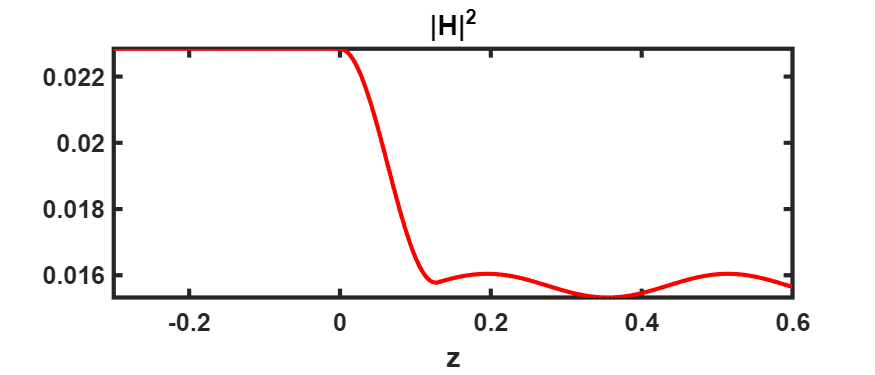

lambda = 0.6; 
theta = 20*pi/180; 
inc = +1; % inc = -1: from down, +1: from up
%
% S-matrix calculation
s = Spectrum(index,geom,lambda,theta,inc);
%
% Field calculation
pol = 0;  % 0: TE, 2: TM
[x,y,z] = deal(0,0,linspace(-.3,.6,201)); % along z-axis
[E,H] = CalculFieldFMM(s,x,y,z,pol);         

% Plot Field distribution
figure('Position',[300  300  560  240]), 
VisuFieldFMM(sum(abs(H).^2,2),x,y,z), axis tight,title('|H|^2') 